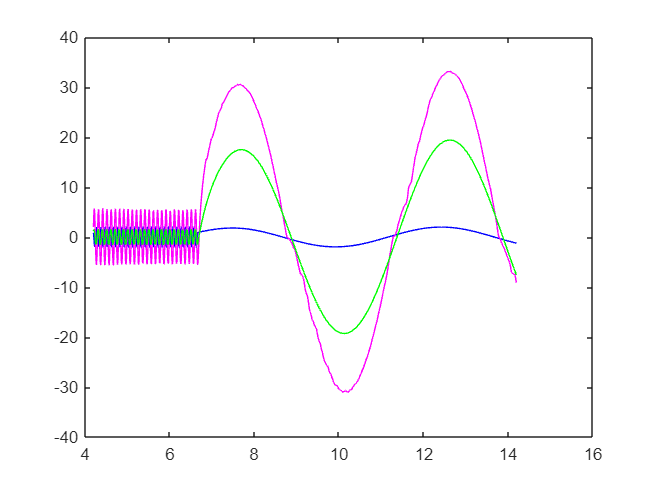

clc, clearvars

%declarando variáveis
char inputFile outPutFile;

% inputFile = input("Enter file name (without the extension): ", 's');
% outputFile = input("Enter file name (without the extension): ", 's');

% adicionando o arquivo
inputFile = 'senf020a200Ent';
outputFile = 'senf020a200Sai';

%ajustando os dados para matrizes de tempo e amplitude
input = importdata(inputFile + ".mat");
inputTime = input.([inputFile '_Time']);
inputAmplitude = input.([inputFile '_Value']);

output = importdata(outputFile + ".mat");
outputTime = output.([outputFile '_Time']);
outputAmplitude = output.([outputFile '_Value']);

%gráfico todo
plot(inputTime, inputAmplitude,'b')
hold on;
plot(outputTime, outputAmplitude(:,1),'m',outputTime, outputAmplitude(:,2),'g')
hold off;

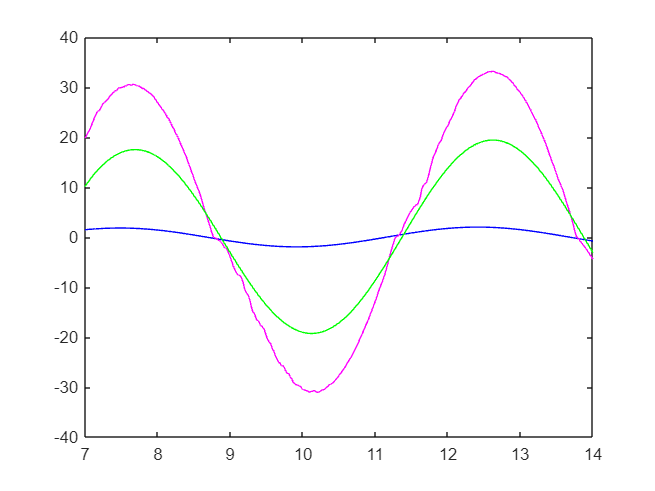


%escolhendo a parte de interesse
startTime = 7;
endTime = 14;
startIndex = find(inputTime >= startTime, 1);
endIndex = find(inputTime >= endTime, 1);

inputTimeRange = inputTime(startIndex:endIndex);
inputAmplitudeRange = inputAmplitude(startIndex:endIndex);

outputTimeRange = outputTime(startIndex:endIndex,:);
outputAmplitudeRange = outputAmplitude(startIndex:endIndex,:);

%gráfico na parte de interesse
plot(inputTimeRange,inputAmplitudeRange,'b')
hold on;
plot(outputTimeRange,outputAmplitudeRange(:,1),'m')
plot(outputTimeRange,outputAmplitudeRange(:,2),'g')
hold off;

int32 N;
N = length(inputTimeRange);

% %comentar isso
% %vamos fazer a fft dos sinais
% 
% frequency = zeros(length(inputTimeRange),1);
% 
% for i = 1:(length(inputTimeRange) -1)
%     frequency(i) = 1/(inputTimeRange(i+1) - inputTimeRange(i));
% end
% 
% for i = 1:length(frequency)
%     frequency(i) = i*frequency(i);
% end

inputFft = fft(inputAmplitudeRange);
outputFft = fft(outputAmplitudeRange);

magnitudeResponse = abs(outputFft./inputFft);
phaseResponse = angle(outputFft./inputFft);

% %comentar isso
% %Plotando o diagrama de Bode
% figure;
% 
% semilogx(frequency,20*log10(magnitudeResponse(1:length(frequency),1)),'m')
% hold on
% semilogx(frequency,20*log10(magnitudeResponse(1:length(frequency),2)),'g')
% grid on
% hold off
% 
% semilogx(frequency, phaseResponse(1:length(frequency),1),'m')
% hold on
% grid on
% semilogx(frequency, phaseResponse(1:length(frequency),2),'g')
% hold off
% 
% plot(frequency,outputFft(:,1),'m')
% title("Single-Sided Amplitude Spectrum of output(t)")
% xlabel("f (Hz)")
% ylabel("|P1(f)|")
% hold on
% 
% plot(frequency,outputFft(:,2),'g')

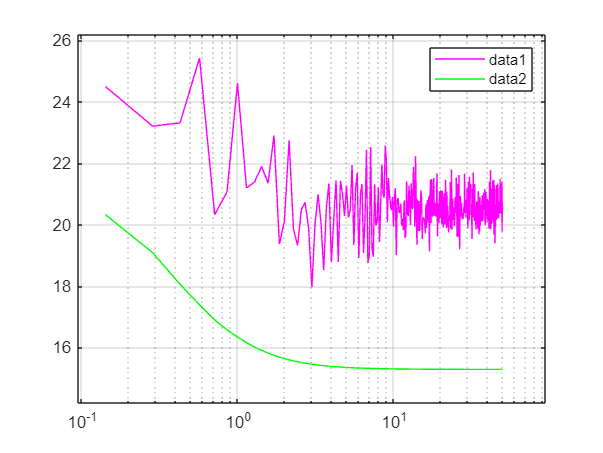

frequencySample = 1/(inputTimeRange(2) - inputTimeRange(1));
frequencies = frequencySample*(0:(N/2))/N;

figure;

semilogx(frequencies,20*log10(magnitudeResponse(1:floor(N/2)+1,1)),'m')
hold on
semilogx(frequencies,20*log10(magnitudeResponse(1:floor(N/2)+1,2)),'g')
hold off
legend
grid on

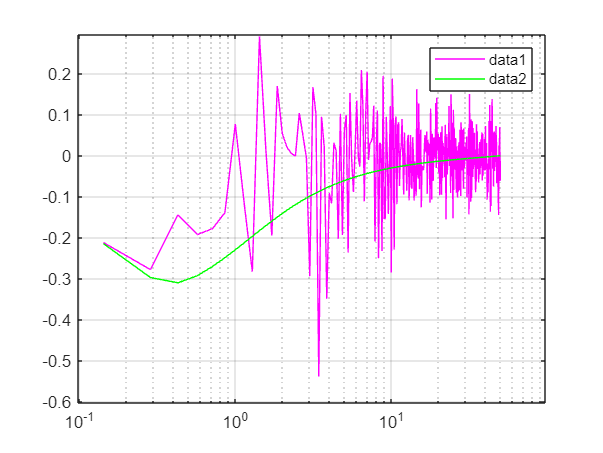


semilogx(frequencies, phaseResponse(1:floor(N/2)+1,1),'m')
hold on
grid on
semilogx(frequencies, phaseResponse(1:floor(N/2)+1,2),'g')
legend
hold off

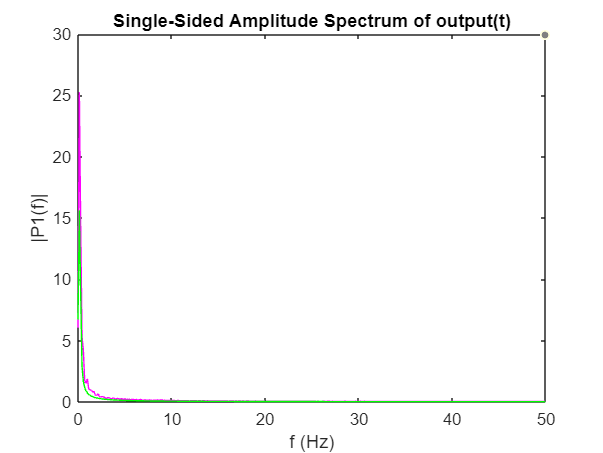

%Vamos tentar filtrar os valores da FFT
P2 = abs(outputFft/N);
P1 = P2(1:floor(N/2)+1,:);
P1(2:end-1) = 2*P1(2:end-1);

plot(frequencies,P1(:,1),'m')
title("Single-Sided Amplitude Spectrum of output(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")
hold on

plot(frequencies,P1(:,2),'g')
hold off

% windowSize = 2;
% b = (1/windowSize)*ones(1,windowSize);
% a = 1;
%
% filteredAmplitude = filter(b, a, outputFft)
% fP2 = abs(filteredAmplitude/N);
% fP1 = fP2(1:floor(N/2)+1,:);
% fP1(2:end-1) = 2*fP1(2:end-1);
%
% plot(frequencies,fP1)

% amplitudeAverage = sum(P1)/length(P1);
% 
% fP1 = zeros(length(P1),2);
% 
% for i=1:length(P1)
%     if P1(i,1) > 5*amplitudeAverage(1,1)
%         fP1(i,1) = P1(i,1);
%     else
%         fP1(i,1) = 0;
%     end
% end
% 
% for i=1:length(P1)
%     if P1(i,2) > 2*amplitudeAverage(1,2)
%         fP1(i,2) = P1(i,2);
%     else
%         fP1(i,2) = 0;
%     end
% end
% 
% peaksfP1  = islocalmax(fP1);
% 
% peaksfP1_1out = P1(peaksfP1(:,1),1);
% peaksfP1_2out = P1(peaksfP1(:,2),2);
% 
% plot(frequencies(peaksfP1(:,1)),peaksfP1_1out,'m*')
% plot(frequencies(peaksfP1(:,2)),peaksfP1_2out,'gx')
% hold off
% title("Single-Sided Amplitude Spectrum of output(t)")
% xlabel("f (Hz)")
% ylabel("|P1(f)|")

magnitudeResponse = abs(outputFft./inputFft);
phaseResponse = angle(outputFft./inputFft);

filteredMagnitudeResponse = magnitudeResponse(1:floor(N/2)+1,:).*peaksfP1;

Unrecognized function or variable 'peaksfP1'.

filteredPhaseResponse = phaseResponse(1:floor(N/2)+1,:).*peaksfP1;

figure;

semilogx(frequencies,20*log10(filteredMagnitudeResponse(:,1)),'m*')
hold on
semilogx(frequencies,20*log10(filteredMagnitudeResponse(:,2)),'gx')
hold off
grid on

semilogx(frequencies, filteredPhaseResponse(:,1),'m*')
hold on
grid on
semilogx(frequencies, filteredPhaseResponse(:,2),'gx')
hold off

% % Find indices of non-zero points
% nonzeroFMRInd = find(filteredMagnitudeResponse(:, 1) ~= 0 & filteredMagnitudeResponse(:, 2) ~= 0);
% nonzeroFPRInd = find(filteredPhaseResponse(:, 1) ~= 0 & filteredPhaseResponse(:, 2) ~= 0);
% 
% % Filter out (0,0) point
% nonZeroFilteredMR = filteredMagnitudeResponse(nonzeroFMRInd, :);
% nonZeroFilteredPR = filteredPhaseResponse(nonzeroFPRInd, :);
% 
% figure;
% 
% semilogx(frequencies,20*log10(nonZeroFilteredMR(:,1)),'m*')
% hold on
% semilogx(frequencies,20*log10(nonZeroFilteredMR(:,2)),'gx')
% hold off
% grid on
% 
% semilogx(frequencies, nonZeroFilteredPR(:,1),'m*')
% hold on
% grid on
% semilogx(frequencies, nonZeroFilteredPR(:,2),'gx')
% hold off

semilogx(frequencies,20*log10(filteredMagnitudeResponse(:,1)),'m*')
hold on
semilogx(frequencies,20*log10(filteredMagnitudeResponse(:,2)),'gx')

semilogx(frequencies,20*log10(magnitudeResponse(1:floor(N/2)+1,1)),'m')
semilogx(frequencies,20*log10(magnitudeResponse(1:floor(N/2)+1,2)),'g')
hold off
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Bode Diagram - Magnitude Response');
grid on

semilogx(frequencies, phaseResponse(1:floor(N/2)+1,1),'m')
hold on
grid on
semilogx(frequencies, phaseResponse(1:floor(N/2)+1,2),'g')

semilogx(frequencies, filteredPhaseResponse(:,1),'m*')
semilogx(frequencies, filteredPhaseResponse(:,2),'gx')
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
title('Bode Diagram - Phase Response');
hold off